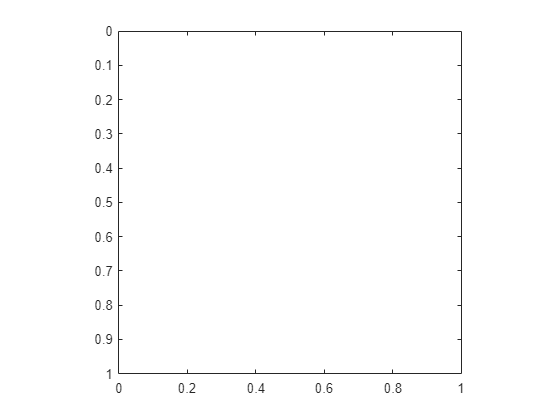

v = linspace(0, 1, 256)';
colormap([v v v]);
a = load('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\pictures.jpg');
image(a')
axis('image')

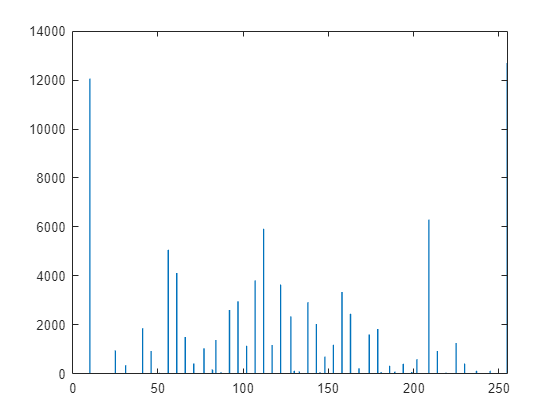

%i display the raw
v = linspace(0, 1, 256)';
colormap([v v v]);

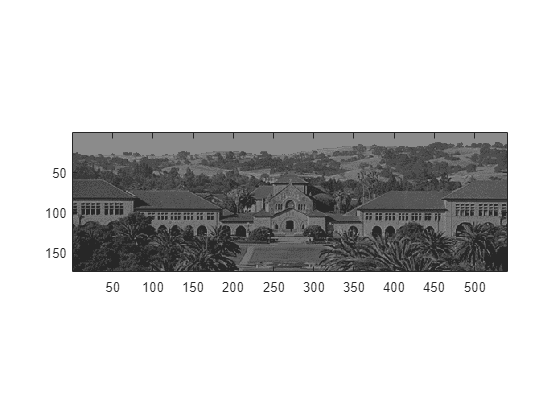

filename = 'C:\Users\HP\Desktop\上课\图像处理代码\For_Students(3)\For Students\lab5prob1data';
fileID = fopen(filename, 'rb');  % 'rb' 表示二进制读取模式
imageData = fread(fileID, [540, Inf], 'uint8'); 
fclose(fileID);  % 关闭文件
image(imageData')
axis('image')


%2 plot the histogram
image_vector = imageData(:)

image_vector =    140
   140
   140
   140
   140
   140
   140
   140
   140
   140


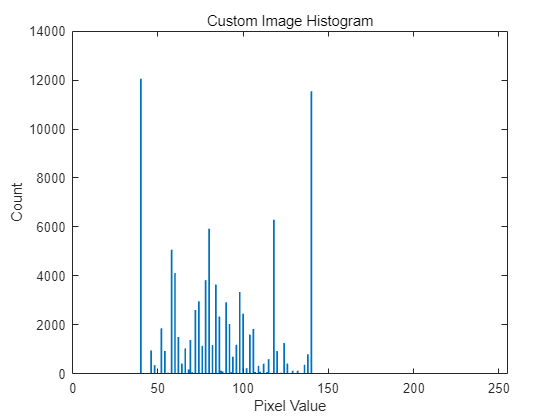

counts = zeros(256, 1);
 for i = 0:255
     counts(i+1) = sum(image_vector == i);
 end
bar(0:255, counts, 'BarWidth', 1, 'EdgeColor', 'none');
xlim([0 255]); 
xlabel('Pixel Value');
ylabel('Count');
title('Custom Image Histogram');

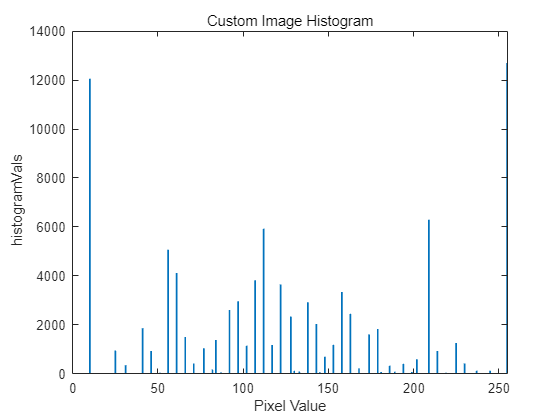


%3 Derive a transformation that yields a mean of 128 and a standard deviation of 80
if size(imageData, 3) == 3
    imageData = rgb2gray(imageData);
end

% Calculate current mean and standard deviation
currentMean = mean(imageData(:));
currentStd = std(double(imageData(:)));

% Apply transformation
newMean = 128;
newStd = 80;
imageData = double(imageData);
scaledImg = (imageData - currentMean) * (newStd / currentStd) + newMean;

% Clip the values to [0, 255]
scaledImg(scaledImg < 0) = 0;
scaledImg(scaledImg > 255) = 255;
scaledImg = uint8(scaledImg);

%Calculate the new histogram
histogramVals = zeros(256,1);
for i = 0:255
    histogramVals(i+1) = sum(scaledImg(:) == i);
end
bar(0:255,  histogramVals, 'BarWidth', 1, 'EdgeColor', 'none');
xlim([0 255]); 
xlabel('Pixel Value');
ylabel(' histogramVals');
title('Custom Image Histogram');

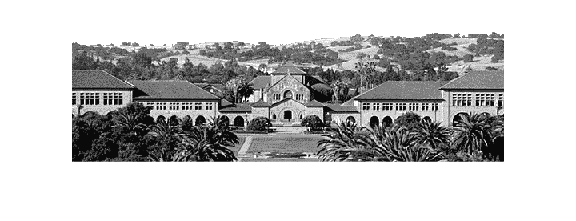

%Display the processed image and the new histogram
imshow(scaledImg');

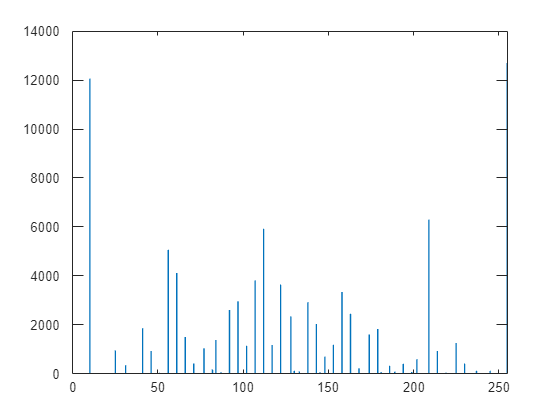

figure;
bar(0:255, histogramVals);
xlim([0 255]); 


% Optionally, you can display the mean and standard deviation of the scaled image
disp(['New Mean: ', num2str(mean(scaledImg(:)))]);

New Mean: 126.6025


disp(['New Std Dev: ', num2str(std(double(scaledImg(:))))]);

New Std Dev: 77.8008


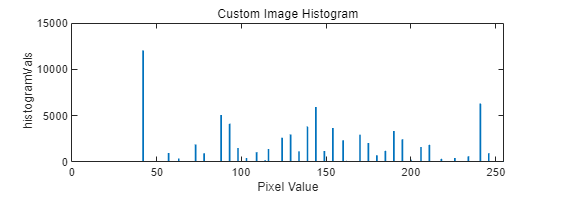

% More stretching
if size(imageData, 3) == 3
    imageData = rgb2gray(imageData);
end

% Calculate current mean and standard deviation
currentMean = mean(imageData(:));
currentStd = std(double(imageData(:)));

% Apply transformation
newMean = 160;
newStd = 80;
imageData = double(imageData);
scaledImg = (imageData - currentMean) * (newStd / currentStd) + newMean;

% Clip the values to [0, 255]
scaledImg(scaledImg < 0) = 0;
scaledImg(scaledImg > 255) = 255;
scaledImg = uint8(scaledImg);

%Calculate the new histogram
histogramVals = zeros(256,1);
for i = 0:255
    histogramVals(i+1) = sum(scaledImg(:) == i);
end
bar(0:255,  histogramVals, 'BarWidth', 1, 'EdgeColor', 'none');
xlim([0 255]); 
xlabel('Pixel Value');
ylabel(' histogramVals');
title('Custom Image Histogram');

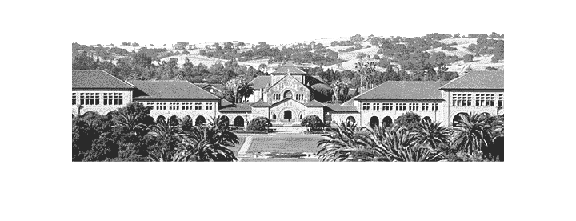

%Display the processed image and the new histogram
imshow(scaledImg');

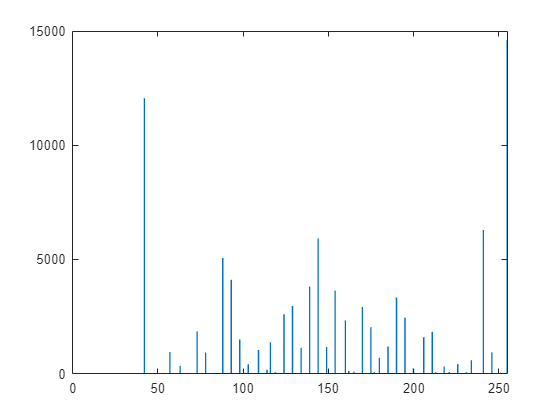

figure;
bar(0:255, histogramVals);
xlim([0 255]); 

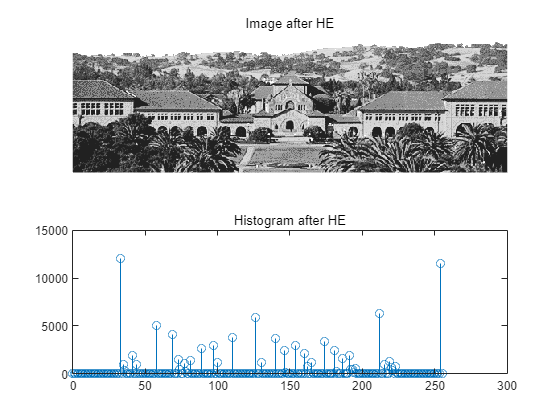

%% Problem 3 - Equalization stretches. ？？？？？？
clear;close all;

id = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(3)\For Students\lab5prob1data','r');
A = fread(id,'uint8');
fclose(id);
l = length(A);
I = uint8(reshape(A,[540,l/540]));
v=linspace(0,1,256)';
%% 3.1
[Pr,~] = imhist(I,256);
Pr = Pr./sum(Pr);
Isz = size(I);
I2 = I;
for i = 1:Isz(1)
    for j = 1:Isz(2)
        m = I(i,j);
        s = HE(256,m+1,Pr);
        I2(i,j) = (round(s));
    end
end
figure(2)
subplot(2,1,1);
imshow(I2');
title('Image after HE');
subplot(2,1,2);
hist2 = Hist(I2);
x2 = hist2(1,:);
y2 = hist2(2,:);
stem(x2,y2);
title('Histogram after HE')

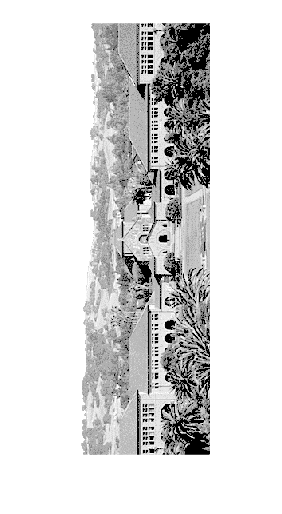

v = linspace(0, 1, 256)';
colormap([v v v]);

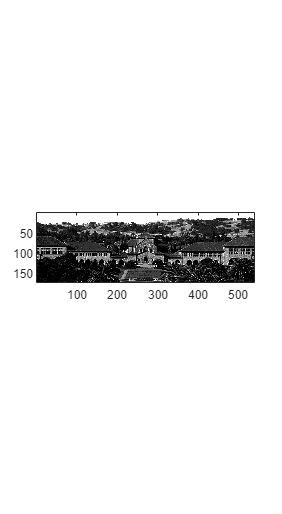

filename = 'C:\Users\HP\Desktop\上课\图像处理代码\For_Students(3)\For Students\lab5prob4data';
fileID = fopen(filename, 'rb');  % 'rb' 表示二进制读取模式
imageData = fread(fileID, [540, Inf], 'uint8'); 
fclose(fileID);  % 关闭文件
image(imageData')
axis('image')

imgData = double(imageData)

imgData =    254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254    33    20    33    28    40    45    40    28    40    45    40    91    45    40    28    40    40    74    40    40    28    45    40    28    28
   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254    74    28    28    40    33    40    33    40    45    28    40    45    28    40    28    45    40    45    40    40    68    59    40    40    40    40
   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254    45    12    40    40    40    40    28    28    40    45    40    28    12    40    45    28    40    40    45    40    68    40    12    10    12
   254   254   254   254   254   254   254   254   254   254   254   254   254   254   

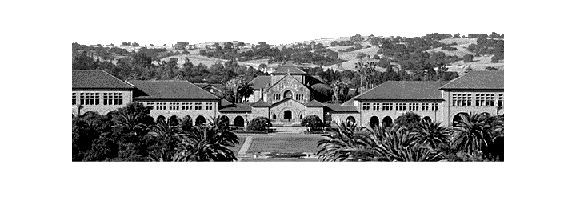


% i. 对图像应用 1/2 次幂拉伸
sqrtImg = stretchImage(imgData, 0.5);
imshow(uint8(sqrtImg')); 

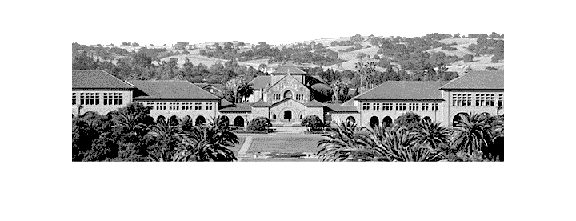

imwrite(uint8(sqrtImg'), 'sqrtImage.png'); 

% ii. 对图像应用 1/3 次幂拉伸（立方根）
cbrtImg = stretchImage(imgData, 1/3);
imshow(uint8(cbrtImg')); 

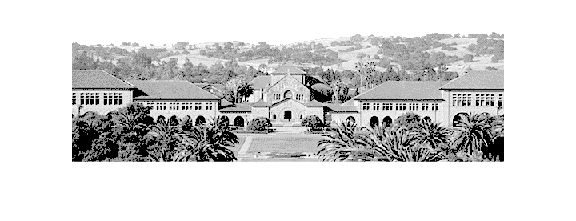

imwrite(uint8(cbrtImg'), 'cbrtImage.png'); 

% iii. 对图像应用 0.2 次幂拉伸
powImg = stretchImage(imgData, 0.2);
imshow(uint8(powImg'));  

imwrite(uint8(powImg'), 'powImage.png');  



function stretchedImg = stretchImage(img, exponent) % 非线性拉伸函数
    % 将图像标准化到 [0,1]
    normalizedImg = (img - min(img(:))) / (max(img(:)) - min(img(:)));
    stretchedImg = normalizedImg .^ exponent;
    % 将结果缩放回 [0,255]
    stretchedImg = stretchedImg * 255;
end

function s = HE(L,k,Pr)
a = L-1;
b = Pr(1:k);
c = sum(b);
s = a*c;
end

function X = Hist(I)
Isz = size(I);
X = zeros(2,256);
X(1,:) = 0:255;
for i = 1:Isz(1)
    for j = 1:Isz(2)
        X(2,I(i,j)+1) = X(2,I(i,j)+1)+1;
    end
end
end
